Controllo se è rimasta aperta la porta seriale

if( exist('STM32_ser') );
    delete(STM32_ser);
    clear STM32_ser;
end

Connetto alla seriale

porte_libere = serialportlist("available")

porte_libere = "COM8"

STM32_ser = serialport(porte_libere(end), 1000000, Timeout=2);
configureTerminator(STM32_ser,"CR");


Prendo costanti di riferimento

STM32_ser.flush
STM32_ser.write('t','char')

const_t30c = STM32_ser.read(1, 'uint16')

const_t30c = 12430


STM32_ser.flush
STM32_ser.write('T','char')

const_t110c = STM32_ser.read(1,"uint16")

const_t110c = 16470


Const1 = 80000;
Ts_diff = const_t110c - const_t30c

Ts_diff = 4040

buff_size = 100

buff_size = 100

STM32_ser.flush
STM32_ser.write('e','char')
buff_data = STM32_ser.read(buff_size,'uint16')

buff_data =        12408       12380       12389       12391       12394       12370       12365       12390       12388       12385       12392       12363       12385       12379       12385       12382       12367       12384       12386       12372       12380       12398       12388       12372       12377       12382       12382       12389       12388       12380       12386       12392       12367       12377       12380       12394       12387       12384       12365       12393       12397       12370       12368       12368       12391       12399       12383       12388       12406       12378


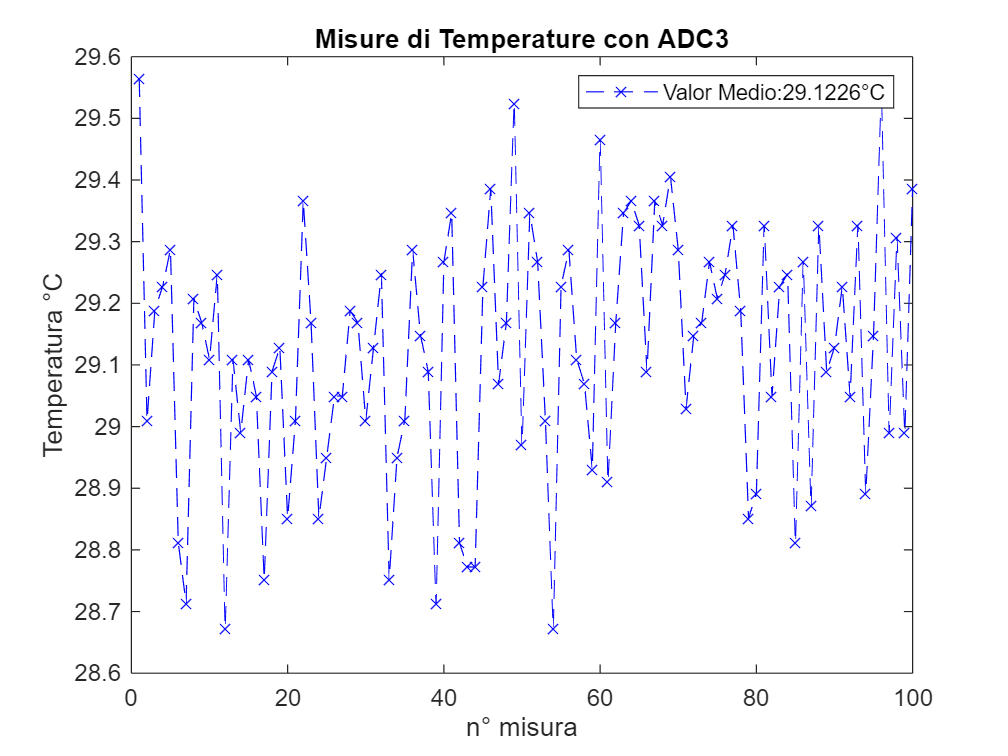


for i=1:length(buff_data)
    % buff_data(i) = 1;
    buff_data(i) = ((Const1*(buff_data(i) - const_t30c)/Ts_diff) + 30000) / 1000;
end
f = figure;
plot(1:buff_size, buff_data, 'b--x');

media = mean(buff_data);

title("Misure di Temperature con ADC3")
xlabel("n° misura")
ylabel("Temperatura °C")
legend("Valor Medio:"+num2str(media)+"°C")